clear all
close all
run ../../../install.m

## 连接动捕SDK

ip = '127.0.0.1';
luster = LuMoSDKMPI(ip);

Loading LuMoSDKCAPI



if(luster.connect() == false)
    error("Run program failed.");
end

Initializing the SDK object...
The SDK object initialized successfully.


## 机器人平台参数-测量

phi = 15; % 靶球直径
h   = 20; % 靶球远端到平台基座的距离
c_bias = 24.5; % 机械臂基座到平台基座的距离
% h_basis = h - phi/2 ; % 基座靶球测到的基座坐标系偏移到机械臂基座坐标系
h_basis = h - phi/2 - c_bias ; % 基座靶球测到的基座坐标系偏移到机械臂基座坐标系

## 建立位置参考 - 初始化（不受力）

% %%% 提取初始位姿 - 作为位移参考 %%%%
frameData = luster.receiveFrame();
markers   = frameData.allMarker;
rigid = frameData.allRigidbody; % base - mideff - endeff

global mark_ind
mark_ind = 8;

% 基座空间位置 - 固定不变，所以只需要提取一次
base          = rigid(1);
base_xyz      = [base.X, base.Y, base.Z];
base_xyz(:,2) = base_xyz(:,2) - h_basis;  % y方向 偏移到机械臂基座端
base_q        = [base.qw, base.qx, base.qy, base.qz];
R_B2G         = quat2dcm(base_q); % 全局坐标系转基座坐标系

% ========= 末端初始位姿 ==========
endeff       = markers(mark_ind);
endeff_xyz   = [endeff.X, endeff.Y, endeff.Z];

delta_EB    = (endeff_xyz - base_xyz)' % 末端执行器 与 基座坐标系的差值，在G系中表示

delta_EB = 3×1 single 列向量
  119.2167
  447.7206
  -84.3038


pos_endeff_ref  = (R_B2G*delta_EB)' % 参考位置，相对基座的位置

pos_endeff_ref = 1×3 single 行向量
  111.6288   84.5971  449.6175



% ========= 中端初始位姿 ==========
mideff       = rigid(2);
mideff_xyz   = [mideff.X, mideff.Y, mideff.Z];

delta_MB        = (mideff_xyz - base_xyz)' % 中端 与 基座坐标系的差值，在G系中表示

delta_MB = 3×1 single 列向量
  115.1607
  216.4651
  -86.4001


pos_mideff_ref  = (R_B2G*delta_MB)'    % 中端参考位置，相对基座的位置

pos_mideff_ref = 1×3 single 行向量
  111.3090   86.7620  218.3273



% ========= 障碍物初始位置，相对于末端 ==========
obst          = rigid(3);
obst_xyz   = [obst.X, obst.Y, obst.Z];

delta_obst        = (obst_xyz - base_xyz)' % 中端 与 基座坐标系的差值，在G系中表示

delta_obst = 3×1 single 列向量
  155.1074
  441.9431
 -172.9106


pos_obst_ref  = (R_B2G*delta_obst)'    % 中端参考位置，相对基座的位置

pos_obst_ref = 1×3 single 行向量
  147.2681  173.3429  444.4485



disp_obst     = (pos_obst_ref - pos_endeff_ref) ./1000 

disp_obst = 1×3 single 行向量
    0.0356    0.0887   -0.0052


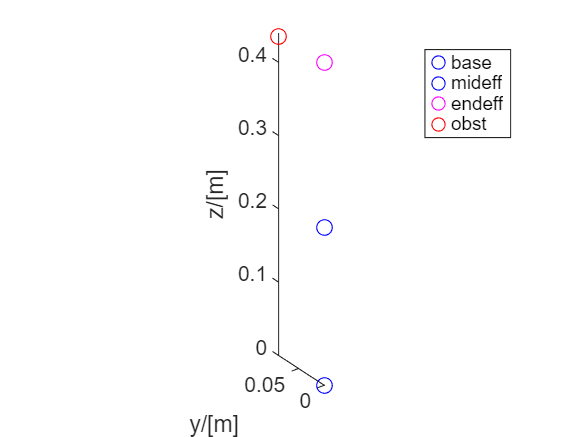

figure; hold on
scatter3(0,0,0,     50,'bo','DisplayName','base')
scatter3(0,0,0.215, 50,'bo','DisplayName','mideff')
scatter3(0,0,0.440, 50,'mo','DisplayName','endeff')
scatter3(disp_obst(1)./1000,disp_obst(2),disp_obst(3)+0.44, 50,'ro','DisplayName','obst')
legend('show')

xlabel('x/[m]')
ylabel('y/[m]')
zlabel('z/[m]')

view(3)
axis equal